prompt = "Altura inicial (Mayor): ";
prompt1 = "Altura ideal: ";
prompt2 = "Altura inicial (Menor): ";
g = 9.81;
coeficiente_friccion = 0.2;

% datos para la cálculos montaña rusa ideal
% la altura ideal es de 1.630002517664
h = input(prompt1);
initial_x = -0.6625553533354;
initial_y = h;
initial_velocity = 0;
potencial_inicial = initial_y*50*g;
cinetica_inicial = (initial_velocity^2)/2;

% datos para cálculos montaña rusa con altura mayor
h_mayor = input(prompt);
f = @(k)(7/3)*k^9-2*k^8-k^7-k^6+(1/2)*k^5-k^4-k^3+4*k^2;
initial_x_mayor = fminbnd(@(k) abs(f(k) - h_mayor), -0.8, -0.6);
initial_y_mayor = h_mayor;
initial_velocity_mayor = 0;
potencial_inicial_mayor = initial_y_mayor*50*g;
cinetica_inicial_mayor = (initial_velocity_mayor^2)/2;
syms p;
j = sqrt(((21*p.^8-16*p.^7-7*p.^6-6*p.^5+(5/2)*p.^4-4*p.^3-3*p.^2+8*p.^1)^2)+1);
distancia_mayor = int(j, initial_x_mayor, 0);


% datos para cálculos montaña rusa con altura menor
h_menor = input(prompt2);
initial_x_menor = fminbnd(@(k) abs(f(k) - h_menor), -0.7, 0);
initial_y_menor = h_menor;
initial_velocity_menor = 0;
potencial_inicial_menor = initial_y_menor*50*9.81;
cinetica_inicial_menor = (initial_velocity_menor^2)/2;
distancia_menor = int(j, initial_x_menor, 0);



% montaña rusa ideal
fprintf('Resultados para la montaña rusa con altura ideal %.2f \n');

Resultados para la montaña rusa con altura ideal 

% Ahora hacemos los cálculos para la montaña ideal
% ideal punto A
cinetica_punto_A1 = (initial_velocity^2)/2;
fprintf('Velocidad punto A: %.2f m/s\n', initial_velocity);

Velocidad punto A: 0.00 m/s


fprintf('Altura punto A: %.2f m\n', initial_y*50);

Altura punto A: 81.50 m


fprintf('Energía cinética punto A: %.2f J\n', cinetica_punto_A1);

Energía cinética punto A: 0.00 J


fprintf('Energía potencial punto A: %.2f J\n', potencial_inicial);

Energía potencial punto A: 799.52 J


fprintf('Suma: %.2f J\n', potencial_inicial+cinetica_inicial);

Suma: 799.52 J




% ideal punto B
coseno1 = cos(deg2rad(67));
F_friccion_B = coeficiente_friccion*g*coseno1;
W_no_conservativa1 = F_friccion_B * 1.8098 * 50;


velocidad_punto_B1 = sqrt(2*(potencial_inicial+cinetica_inicial-W_no_conservativa1));
cinetica_punto_B1 = 0.5*velocidad_punto_B1^2;
fprintf('Velocidad punto B: %.2f m/s\n', velocidad_punto_B1);

Velocidad punto B: 38.21 m/s


fprintf('Altura punto B: 0 %.2f m\n');

Altura punto B: 0 

fprintf('Energía cinética punto B: %.2f J\n', cinetica_punto_B1);

Energía cinética punto B: 730.15 J


fprintf('Energía potencial punto B: 0 %.2f J\n');

Energía potencial punto B: 0 

fprintf('Trabajo de la fricción punto A a B:  %.2f J\n', W_no_conservativa1);

Trabajo de la fricción punto A a B:  69.37 J


fprintf('Suma:  %.2f J\n', W_no_conservativa1+cinetica_punto_B1);

Suma:  799.52 J



% ideal punto C
potencial_punto_C = 1.3088241880876*50*9.81;
coseno2 = cos(deg2rad(59));
F_friccion_C = coeficiente_friccion*g*coseno2;
W_no_conservativa2 = F_friccion_C * 1.56288*50;

velocidad_punto_C1 = sqrt(2*(cinetica_punto_B1-potencial_punto_C-W_no_conservativa2));
cinetica_punto_C1 = 0.5*velocidad_punto_C1^2;
fprintf('Velocidad punto C: %.2f m/s\n', velocidad_punto_C1);

Velocidad punto C: 4.29 m/s


fprintf('Altura punto C: %.2f m\n', 1.3088241880876*50);

Altura punto C: 65.44 m


fprintf('Energía cinética punto C: %.2f J\n', cinetica_punto_C1);

Energía cinética punto C: 9.20 J


fprintf('Energía potencial punto C:  %.2f J\n', potencial_punto_C);

Energía potencial punto C:  641.98 J


fprintf('Trabajo de la fricción punto B a C:  %.2f J\n', W_no_conservativa2);

Trabajo de la fricción punto B a C:  78.96 J


fprintf('Suma:  %.2f J\n', W_no_conservativa1+W_no_conservativa2+cinetica_punto_C1+potencial_punto_C);

Suma:  799.52 J



% ideal punto D
potencial_punto_D = 0.0708723617455*50*9.81;
coseno3 = cos(deg2rad(72));
F_friccion_D = coeficiente_friccion*g*coseno3;
W_no_conservativa3 = F_friccion_D * 1.32671*50;

velocidad_punto_D1 = sqrt(2*(cinetica_punto_C1+potencial_punto_C-potencial_punto_D-W_no_conservativa3));
cinetica_punto_D1 = 0.5*velocidad_punto_D1^2;
fprintf('Velocidad punto D: %.2f m/s\n', velocidad_punto_D1);

Velocidad punto D: 33.95 m/s


fprintf('Altura punto D: %.2f m\n', 0.0708723617455*50);

Altura punto D: 3.54 m


fprintf('Energía cinética punto D: %.2f J\n', cinetica_punto_D1);

Energía cinética punto D: 576.20 J


fprintf('Energía potencial punto D:  %.2f J\n', potencial_punto_D);

Energía potencial punto D:  34.76 J


fprintf('Trabajo de la fricción punto B a C:  %.2f J\n', W_no_conservativa3);

Trabajo de la fricción punto B a C:  40.22 J


fprintf('Suma:  %.2f J\n', W_no_conservativa1+W_no_conservativa2+W_no_conservativa3+cinetica_punto_D1+potencial_punto_D);

Suma:  799.52 J



% variables para graficar
x=initial_x;
y=initial_y;
x_data = [];
y_data = [];

%lista con gráfica ideal

% graficar 
if double(velocidad_punto_C1) <= 0 % si la montaña rusa no tiene velocidad suficiente
    h_max = ((((velocidad_punto_B1).^2)*(sin(deg2rad(59))))/(2*(g-F_friccion_C)))/50;
    x_max = (h_max/(tan(deg2rad(59))));
    while x<=double(x_max)
        x_data = [x_data, x];
        y_data = [y_data, y];
        x = x+0.01;
        y = (7/3)*x.^9-2*x.^8-x.^7-x.^6+(1/2)*x.^5-x.^4-x.^3+4*x.^2;    
    end
elseif double(velocidad_punto_C1) > 4.95
    while x<=0.7907806984336
        x_data = [x_data, x];
        y_data = [y_data, y];
        x = x+0.01;
        y = (7/3)*x.^9-2*x.^8-x.^7-x.^6+(1/2)*x.^5-x.^4-x.^3+4*x.^2;    
    end
    while x<1.2
        x_data = [x_data, x];
        y_data = [y_data, y];
        x = x+0.01;
        y = -1 * ((x - 0.905).^2) + 1.325;
    end
else 
    while x<=1.2
    x_data = [x_data, x];
    y_data = [y_data, y];
    x = x+0.01;
    y = (7/3)*x.^9-2*x.^8-x.^7-x.^6+(1/2)*x.^5-x.^4-x.^3+4*x.^2;
    
    end
end


%grafica
figure;
for i = 1:length(x_data)
    plot(x_data(1:i), y_data(1:i), 'b');
    xlabel('Distancia (1 unidad = 1 metro)');
    ylabel('Altura (1 unidad = 1 metro)');
    title('Montaña rusa ideal')
    grid on;
    pause(0.1);
end
hold on



% montaña rusa con altura mayor a la ideal
fprintf('Resultados para la montaña rusa con altura mayor a la ideal %.2f \n');

Resultados para la montaña rusa con altura mayor a la ideal 

% Ahora hacemos los cálculos para la montaña rusa con altura mayor a la ideal
% mayor punto A
cinetica_punto_A2 = (initial_velocity_mayor^2)/2;
fprintf('Velocidad punto A: %.2f m/s\n', initial_velocity_mayor);

Velocidad punto A: 0.00 m/s


fprintf('Altura punto A: %.2f m\n', initial_y_mayor*50);

Altura punto A: 90.00 m


fprintf('Energía cinética punto A: %.2f J\n', cinetica_punto_A2);

Energía cinética punto A: 0.00 J


fprintf('Energía potencial punto A: %.2f J\n', potencial_inicial_mayor);

Energía potencial punto A: 882.90 J


fprintf('Suma: %.2f J\n', potencial_inicial_mayor+cinetica_inicial_mayor);

Suma: 882.90 J



% mayor punto B
coseno1 = cos(deg2rad(67));
F_friccion_B = coeficiente_friccion*g*coseno1;
W_no_conservativa1_mayor = F_friccion_B * distancia_mayor * 50;


velocidad_punto_B2 = sqrt(2*(potencial_inicial_mayor+cinetica_inicial_mayor-W_no_conservativa1_mayor));
cinetica_punto_B2 = 0.5*velocidad_punto_B2^2;
fprintf('Velocidad punto B: %.2f m/s\n', velocidad_punto_B2);

Velocidad punto B: 40.16 m/s


fprintf('Altura punto B: 0 %.2f m\n');

Altura punto B: 0 

fprintf('Energía cinética punto B: %.2f J\n', cinetica_punto_B2);

Energía cinética punto B: 806.42 J


fprintf('Energía potencial punto B: 0 %.2f J\n');

Energía potencial punto B: 0 

fprintf('Trabajo de la fricción punto A a B:  %.2f J\n', W_no_conservativa1_mayor);

Trabajo de la fricción punto A a B:  76.48 J


fprintf('Suma:  %.2f J\n', W_no_conservativa1_mayor+cinetica_punto_B2);

Suma:  882.90 J




% mayor punto C
potencial_punto_C = 1.3088241880876*50*9.81;
coseno2 = cos(deg2rad(59));
F_friccion_C = coeficiente_friccion*g*coseno2;
W_no_conservativa2 = F_friccion_C * 1.56288*50;

velocidad_punto_C2 = sqrt(2*(cinetica_punto_B2-potencial_punto_C-W_no_conservativa2));
cinetica_punto_C2 = 0.5*velocidad_punto_C2^2;
fprintf('Velocidad punto C: %.2f m/s\n', velocidad_punto_C2);

Velocidad punto C: 13.08 m/s


fprintf('Altura punto C: %.2f m\n', 1.3088241880876*50);

Altura punto C: 65.44 m


fprintf('Energía cinética punto C: %.2f J\n', cinetica_punto_C2);

Energía cinética punto C: 85.48 J


fprintf('Energía potencial punto C:  %.2f J\n', potencial_punto_C);

Energía potencial punto C:  641.98 J


fprintf('Trabajo de la fricción punto B a C:  %.2f J\n', W_no_conservativa2);

Trabajo de la fricción punto B a C:  78.96 J


fprintf('Suma:  %.2f J\n', W_no_conservativa1_mayor+W_no_conservativa2+cinetica_punto_C2+potencial_punto_C);

Suma:  882.90 J




% mayor punto D
potencial_punto_D = 0.0708723617455*50*9.81;
coseno3 = cos(deg2rad(72));
F_friccion_D = coeficiente_friccion*g*coseno3;
W_no_conservativa3 = F_friccion_D * 1.32671*50;

velocidad_punto_D2 = sqrt(2*(cinetica_punto_C2+potencial_punto_C-potencial_punto_D-W_no_conservativa3));
cinetica_punto_D2 = 0.5*velocidad_punto_D2^2;
fprintf('Velocidad punto D: %.2f m/s\n', velocidad_punto_D2);

Velocidad punto D: 36.12 m/s


fprintf('Altura punto D: %.2f m\n', 0.0708723617455*50);

Altura punto D: 3.54 m


fprintf('Energía cinética punto D: %.2f J\n', cinetica_punto_D2);

Energía cinética punto D: 652.48 J


fprintf('Energía potencial punto D:  %.2f J\n', potencial_punto_D);

Energía potencial punto D:  34.76 J


fprintf('Suma:  %.2f J\n', W_no_conservativa1_mayor+W_no_conservativa2+W_no_conservativa3+cinetica_punto_D2+potencial_punto_D);

Suma:  882.90 J



% variables para graficar la montaña rusa con altura mayor a la ideal
x_mayor=initial_x_mayor;
y_mayor=initial_y_mayor;
x_data_mayor = [];
y_data_mayor = [];
x= initial_x_mayor;
y= initial_y_mayor;

% Graficar montaña rusa con altura mayor a la ideal
if double(velocidad_punto_C2) <= 0 % si la montaña rusa no tiene velocidad suficiente
    h_max = ((((velocidad_punto_B2).^2)*(sin(deg2rad(59))))/(2*(g-F_friccion_C)))/50;
    x_max = (h_max/(tan(deg2rad(59))));
    while x<=double(x_max)
        x_data_mayor = [x_data_mayor, x];
        y_data_mayor = [y_data_mayor, y];
        x = x+0.01;
        y = (7/3)*x.^9-2*x.^8-x.^7-x.^6+(1/2)*x.^5-x.^4-x.^3+4*x.^2;    
    end
elseif double(velocidad_punto_C2) > 4.95
    while x<=0.7907806984336
        x_data_mayor = [x_data_mayor, x];
        y_data_mayor = [y_data_mayor, y];
        x = x+0.01;
        y = (7/3)*x.^9-2*x.^8-x.^7-x.^6+(1/2)*x.^5-x.^4-x.^3+4*x.^2;    
    end
    while x<1.2
        x_data_mayor = [x_data_mayor, x];
        y_data_mayor = [y_data_mayor, y];
        x = x+0.01;
        y = -1 * ((x - 0.905).^2) + 1.325;
    end
else 
    while x<=1.2
    x_data_mayor = [x_data_mayor, x];
    y_data_mayor = [y_data_mayor, y];
    x = x+0.01;
    y = (7/3)*x.^9-2*x.^8-x.^7-x.^6+(1/2)*x.^5-x.^4-x.^3+4*x.^2;
    
    end
end



for i = 1:length(x_data_mayor)
    plot(x_data_mayor(1:i), y_data_mayor(1:i), 'g');
    xlabel('Distancia (1 unidad = 50 metros)');
    ylabel('Altura (1 unidad = 50 metros)');
    title('Montaña rusa con altura mayor a la ideal')
    grid on;
    pause(0.1);
end
hold on



% montaña rusa con altura menor a la ideal
fprintf('Resultados para la montaña rusa con altura menor a la ideal %.2f \n');

Resultados para la montaña rusa con altura menor a la ideal 

% Ahora hacemos los cálculos para la montaña rusa con altura menor a la ideal
% menor punto A
cinetica_punto_A3 = (initial_velocity_menor^2)/2;
fprintf('Velocidad punto A: %.2f m/s\n', initial_velocity_menor);

Velocidad punto A: 0.00 m/s


fprintf('Altura punto A: %.2f m\n', initial_y_menor*50);

Altura punto A: 65.00 m


fprintf('Energía cinética punto A: %.2f J\n', cinetica_punto_A3);

Energía cinética punto A: 0.00 J


fprintf('Energía potencial punto A: %.2f J\n', potencial_inicial_menor);

Energía potencial punto A: 637.65 J


fprintf('Suma: %.2f J\n', potencial_inicial_menor+cinetica_inicial_menor);

Suma: 637.65 J



% menor punto B
coseno1 = cos(deg2rad(67));
F_friccion_B = coeficiente_friccion*g*coseno1;
W_no_conservativa1_menor = F_friccion_B * distancia_menor * 50;


velocidad_punto_B3 = sqrt(2*(potencial_inicial_menor+cinetica_inicial_menor-W_no_conservativa1_menor));
cinetica_punto_B3 = 0.5*velocidad_punto_B3^2;
fprintf('Velocidad punto B: %.2f m/s\n', velocidad_punto_B3);

Velocidad punto B: 34.10 m/s


fprintf('Altura punto B: 0 %.2f m\n');

Altura punto B: 0 

fprintf('Energía cinética punto B: %.2f J\n', cinetica_punto_B3);

Energía cinética punto B: 581.41 J


fprintf('Energía potencial punto B: 0 %.2f J\n');

Energía potencial punto B: 0 

fprintf('Trabajo de la fricción punto A a B:  %.2f J\n', W_no_conservativa1_menor);

Trabajo de la fricción punto A a B:  56.24 J


fprintf('Suma:  %.2f J\n', W_no_conservativa1_menor+cinetica_punto_B3);

Suma:  637.65 J




% menor punto C
potencial_punto_C = 1.3088241880876*50*9.81;
coseno2 = cos(deg2rad(59));
F_friccion_C = coeficiente_friccion*g*coseno2;
W_no_conservativa2 = F_friccion_C * 1.56288*50;

velocidad_punto_C3 = sqrt(2*(cinetica_punto_B3-potencial_punto_C-W_no_conservativa2));
cinetica_punto_C3 = 0.5*velocidad_punto_C3^2;
fprintf('Velocidad punto C: %.2f m/s\n', velocidad_punto_C3);

Velocidad punto C: 0.00 m/s


fprintf('Altura punto C: %.2f m\n', 1.3088241880876*50);

Altura punto C: 65.44 m


fprintf('Energía cinética punto C: %.2f J\n', cinetica_punto_C3);

Energía cinética punto C: -139.54 J


fprintf('Energía potencial punto C:  %.2f J\n', potencial_punto_C);

Energía potencial punto C:  641.98 J


fprintf('Trabajo de la fricción punto B a C:  %.2f J\n', W_no_conservativa2);

Trabajo de la fricción punto B a C:  78.96 J


fprintf('Suma:  %.2f J\n', W_no_conservativa1_menor+W_no_conservativa2+cinetica_punto_C3+potencial_punto_C);

Suma:  637.65 J




% menor punto D
potencial_punto_D = 0.0708723617455*50*9.81;
coseno3 = cos(deg2rad(72));
F_friccion_D = coeficiente_friccion*g*coseno3;
W_no_conservativa3 = F_friccion_D * 1.32671*50;

velocidad_punto_D3 = sqrt(2*(cinetica_punto_C3+potencial_punto_C-potencial_punto_D-W_no_conservativa3));
cinetica_punto_D3 = 0.5*velocidad_punto_D3^2;
fprintf('Velocidad punto D: %.2f m/s\n', velocidad_punto_D3);

Velocidad punto D: 29.24 m/s


fprintf('Altura punto D: %.2f m\n', 0.0708723617455*50);

Altura punto D: 3.54 m


fprintf('Energía cinética punto D: %.2f J\n', cinetica_punto_D3);

Energía cinética punto D: 427.46 J


fprintf('Energía potencial punto D:  %.2f J\n', potencial_punto_D);

Energía potencial punto D:  34.76 J


fprintf('Suma:  %.2f J\n', W_no_conservativa1_menor+W_no_conservativa2+W_no_conservativa3+cinetica_punto_D3+potencial_punto_D);

Suma:  637.65 J


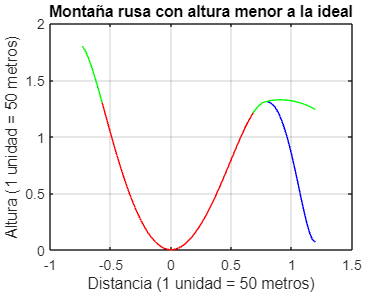


% variables para graficar la montaña rusa con altura menor a la ideal
x_menor=initial_x_menor;
y_menor=initial_y_menor;
x_data_menor = [];
y_data_menor = [];
x= initial_x_menor;
y= initial_y_menor;

% Graficar montaña rusa con altura menor a la ideal
if double(velocidad_punto_C3) <= 0 % si la montaña rusa no tiene velocidad suficiente
    h_max = ((((velocidad_punto_B3).^2)*(sin(deg2rad(59))))/(2*(g-F_friccion_C)))/50;
    x_max = (h_max/(tan(deg2rad(59))));
    while x<=double(x_max)
        x_data_menor = [x_data_menor, x];
        y_data_menor = [y_data_menor, y];
        x = x+0.01;
        y = (7/3)*x.^9-2*x.^8-x.^7-x.^6+(1/2)*x.^5-x.^4-x.^3+4*x.^2;    
    end
elseif double(velocidad_punto_C3) > 4.95 % si la montaña rusa excede la velocidad crítica
    while x<=0.7907806984336
        x_data_menor = [x_data_menor, x];
        y_data_menor = [y_data_menor, y];
        x = x+0.01;
        y = (7/3)*x.^9-2*x.^8-x.^7-x.^6+(1/2)*x.^5-x.^4-x.^3+4*x.^2;    
    end
    while x<1.2
        x_data_menor = [x_data_menor, x];
        y_data_menor = [y_data_menor, y];
        x = x+0.01;
        y = -1 * ((x - 0.905).^2) + 1.325;
    end

else  % si la velocidad tiene velocidad perfecta
    while x<=1.2
    x_data_menor = [x_data_menor, x];
    y_data_menor = [y_data_menor, y];
    x = x+0.01;
    y = (7/3)*x.^9-2*x.^8-x.^7-x.^6+(1/2)*x.^5-x.^4-x.^3+4*x.^2;
    end
end



for i = 1:length(x_data_menor)
    plot(x_data_menor(1:i), y_data_menor(1:i), 'r');
    xlabel('Distancia (1 unidad = 50 metros)');
    ylabel('Altura (1 unidad = 50 metros)');
    title('Montaña rusa con altura menor a la ideal')
    grid on;
    pause(0.1);
end
hold on
hold off 